This script is a matlab live script (mlx file).

The code is written in matlab --  to run this file, 

1 -- select a section you want to run and click the mouse right button and select "Run Section"

2 -- The section will run and the outputs are produced.

3 -- The first point is possible only when all the variables are loaded or else run each section in order.

4 -- To run all the sections at once click on the run button on the top menu.

------------------------------------------------WORKING---------------------------------------------------

1 -- imread() -- it is used to read an image.

2 -- figure -- It is used to generate a figure window

3 -- imshow() -- it is used to display the image

4 -- imwrite() -- it is used to write the image(saving the image to the system)

5 -- title -- gives name to a picture

6 -- imresize() -- used to resize the image

7 -- imcrop() -- used to crop the image

8 -- rgb2hsv -- converts rgb to HSV

9 -- histeq -- used to increase the contrast of the image.

10 -- histogram -- used to visualize the distribution of data

11 -- imhist() -- shows the distribution of pixel intensities

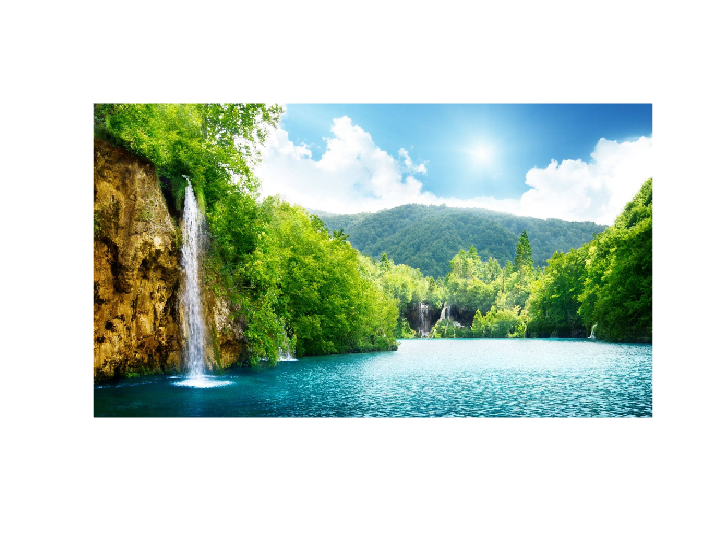

% step 1: Reading and displaying the image
inputImage = imread('pic1.jpg');
figure;
imshow(inputImage);

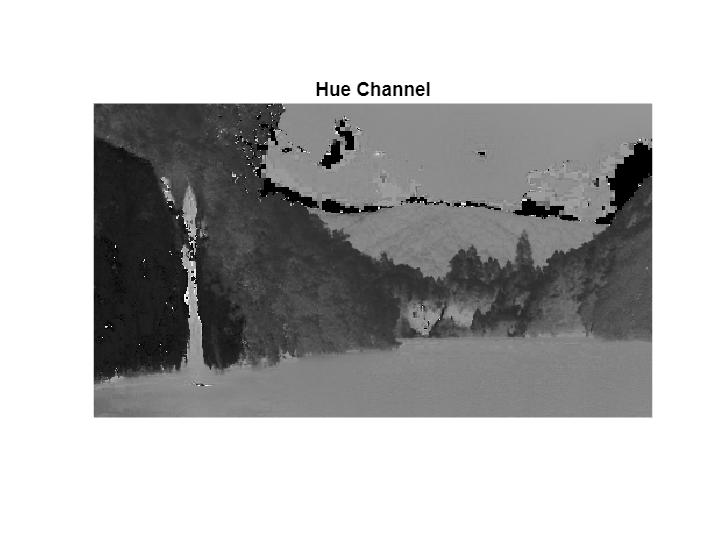

% Step 2: Converting to HSV format and displaying channels separately
hsvImage = rgb2hsv(inputImage);
figure;
% displaying the Hue channel
imshow(hsvImage(:,:,1));
imwrite(hsvImage(:,:,1), 'Hue.png');
title('Hue Channel');

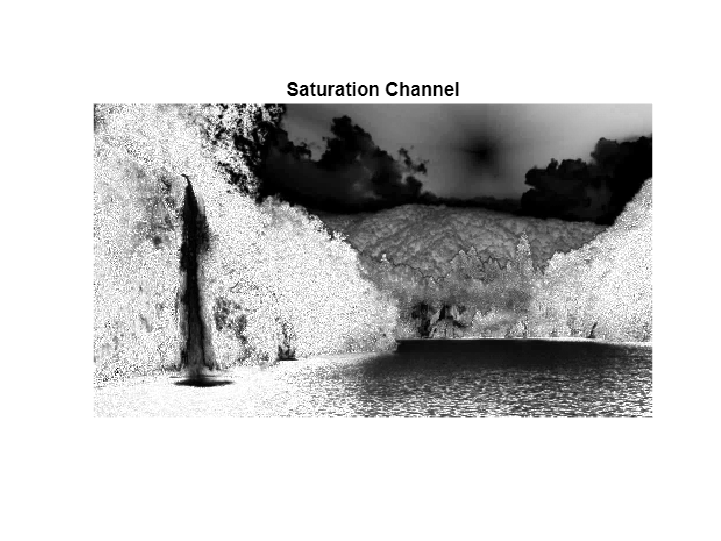

% displaying the Saturation channel
imshow(hsvImage(:,:,2));
imwrite(hsvImage(:,:,2), 'Saturation.png');
title('Saturation Channel');

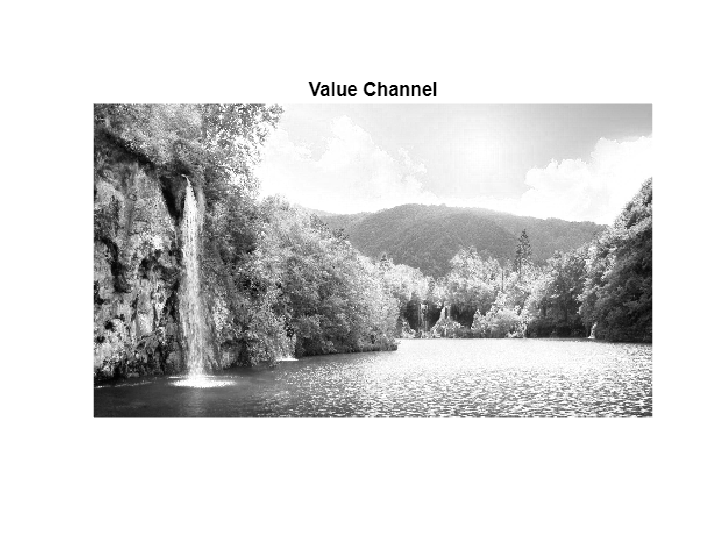

% displaying the Value (brightness) channel
imshow(hsvImage(:,:,3));
imwrite(hsvImage(:,:,3), 'Value.png');
title('Value Channel');

% Step 3: Increasing the size of the image (image * 2) amnd cropping the enlarged image
enlargedImage = imresize(inputImage, 2);
sz = size(enlargedImage);
fprintf('Image dimensions: %d pixels (height) x %d pixels (width) x %d channels\n', sz(1), sz(2), sz(3));

Image dimensions: 2160 pixels (height) x 3840 pixels (width) x 3 channels


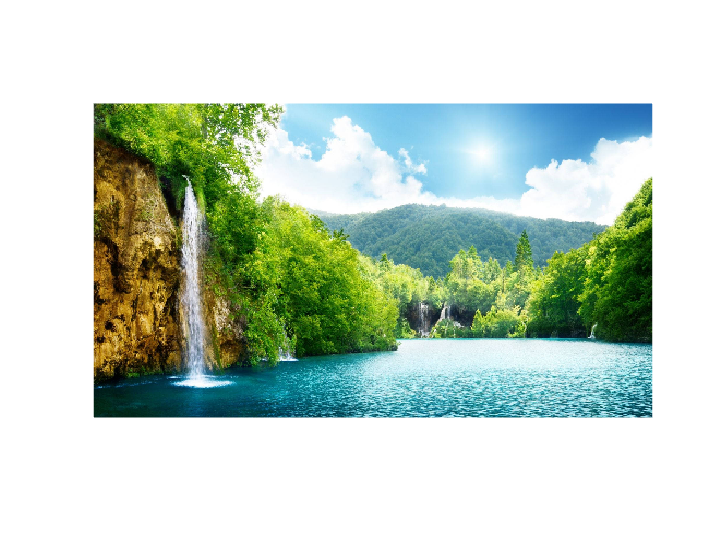

imwrite(enlargedImage,"enlarged.png");
figure;
imshow(enlargedImage);

croppedImage = imcrop(enlargedImage, [1, 1, size(inputImage, 2) - 1, size(inputImage, 1) - 1]);
imwrite(croppedImage,"cropped.png");
sz = size(croppedImage);
fprintf('Image dimensions: %d pixels (height) x %d pixels (width) x %d channels\n', sz(1), sz(2), sz(3));

Image dimensions: 1080 pixels (height) x 1920 pixels (width) x 3 channels


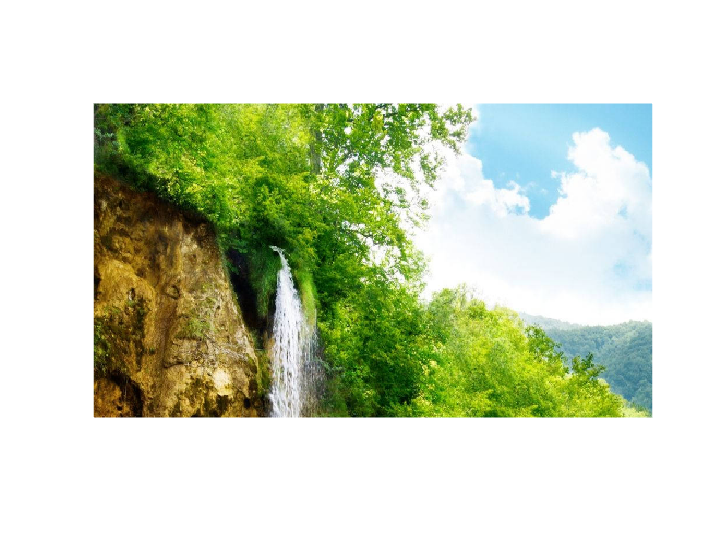

figure;
imshow(croppedImage);

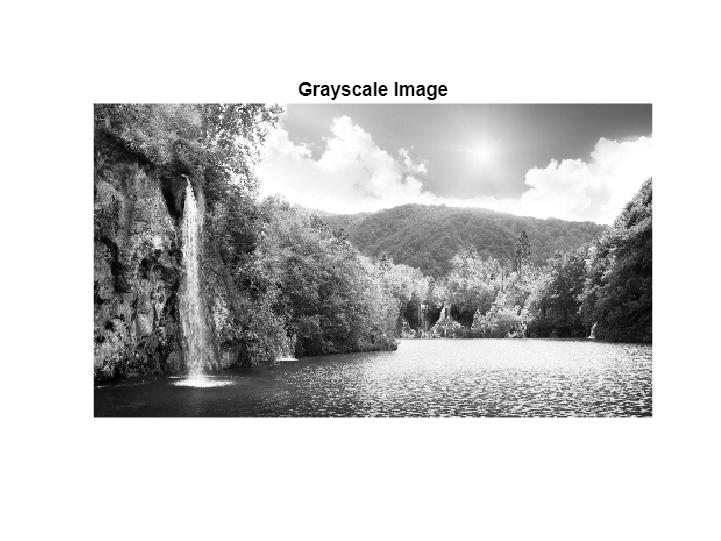

% Step 4: Converting the color image to grayscale
grayImage = rgb2gray(inputImage);
figure;
imwrite(grayImage,'grayImg.png')
% Displaying the grayscale image
imshow(grayImage);
title('Grayscale Image');

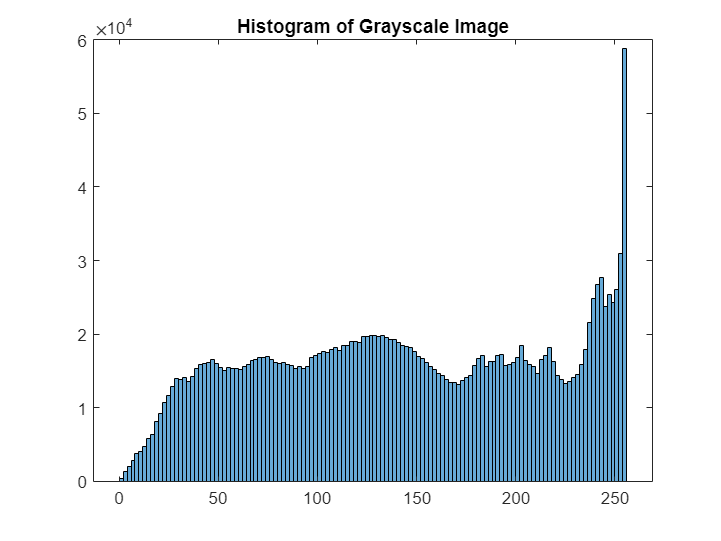

% Displaying the histogram of the grayscale image
histogram(grayImage);
title('Histogram of Grayscale Image');

% Step 6: Perform histogram matching and save the result
outputImage = histogramMatching(grayImage, croppedImage);
imwrite(outputImage, 'final.jpg');

histogram matching function

function matchedImage = histogramMatching(iMat1, iMat2)
    % Convert to grayscale if input images are color
    if size(iMat1, 3) == 3
        iMat1 = rgb2gray(iMat1);
    end
    if size(iMat2, 3) == 3
        iMat2 = rgb2gray(iMat2);
    end
    
    % histogram matching
    iMat2_matched = histeq(iMat2, imhist(iMat1));
    
    % Convert to color if necessary
    if size(iMat1, 3) == 3
        iMat2_matched = repmat(iMat2_matched, [1, 1, 3]);
    end
    matchedImage = iMat2_matched;
end